%https://www.youtube.com/watch?v=UnXDQmjYvDk&list=PLn8PRpmsu08oLufaYWEvcuez8Rq7q4O7D&index=32

%Sets program path to the parent of the current file
%This is necessary to make load work in any computer
CurrFPath = matlab.desktop.editor.getActiveFilename;
CurrFPath = CurrFPath(1:end-14);
cd(CurrFPath)

## Load Ground Truth


load('gangster_labels.mat')

%Create training data from ground truth
    %In case of multiple labels in the object:
gangster_truth = selectLabels(gTruth,'gangster')

gangster_truth =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [1×5 table]
           LabelData: [45×1 table]


%Create folder for training data
%if isfolder(fullfile('training_data'))
%   cd training_data
%else
%    mkdir training_data
%end
%addpath('training_data')


%extracts a subset of ground truth dataset
training_data = objectDetectorTrainingData(gangster_truth)

training_data = 45×2 table
                                 imageFilename                                    gangster  
    ________________________________________________________________________    ____________

    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate10_A.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate11_A.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate11_B.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate12_A.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate12_B.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate13_A.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate13_B.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate1

summary(training_data)

Variables:

    imageFilename: 45×1 cell array of character vectors

    gangster: 45×1 cell



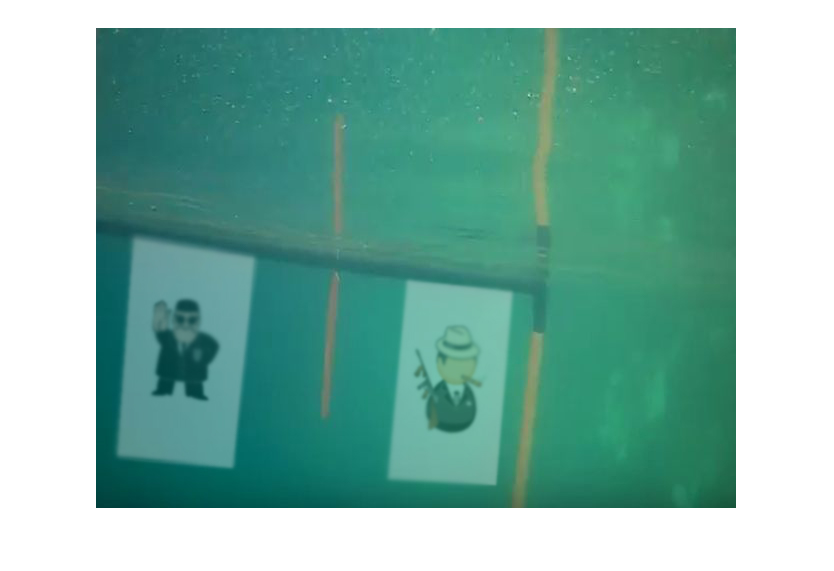

%This segment of code extracts the image size (x,y) for each image in the
%training data
imageSizes = table('Size', [height(training_data), 2], 'VariableTypes', {'double', 'double'}, 'VariableNames', {'X', 'Y'});
 for k=1:height(training_data)
    img = imread(char(training_data.('imageFilename')(k))); 
    ims = imshow(img);
    % Get pixel dimensions of image 
    imagePixelDimX = [ims.XData(2)]; % width in pixels
    imagePixelDimY = [ims.YData(2)]; % height in pixels
    imageSizes.('X')(k) = imagePixelDimX;
    imageSizes.('Y')(k) = imagePixelDimY;
 end

 
 %Here it adds the columns of size x and size y to each picture in the
 %training data
 
 training_data = [training_data imageSizes];

%train de ACF detector
detector = trainACFObjectDetector(training_data,'NumStages',5)

ACF Object Detector Training
The training will take 5 stages. The model size is 67x47.
Sample positive examples(~100% Completed)
Compute approximation coefficients...Completed.
Compute aggregated channel features...Completed.
--------------------------------------------
Stage 1:
Sample negative examples(~100% Completed)
Compute aggregated channel features...Completed.
Train classifier with 45 positive examples and 225 negative examples...Completed.
The trained classifier has 19 weak learners.
--------------------------------------------
Stage 2:
Sample negative examples(~100% Completed)
Found 225 new negative examples for training.
Compute aggregated channel features...Completed.
Train classifier with 45 positive examples and 225 negative examples...Completed.
The trained classifier has 26 weak learners.
--------------------------------------------
Stage 3:
Sample negative examples(~100% Completed)
Found 138 new negative examples for training.
Compute aggregated channel features...Comp

detector =   acfObjectDetector with properties:

             ModelName: 'gangster'
    ObjectTrainingSize: [67 47]
       NumWeakLearners: 56


save('gangster_detector.mat','detector');
%rmpath('training_data');

% Specify the folder where the files are.
cd train_data/

% Assign train data folder path to var myFolder
myFolder = pwd;

% Gets a list of all files in the folder with .jpg extension
filePattern = fullfile(myFolder, '*.jpg');
theFiles = dir(filePattern);
%Create an array with the name of all files
FilesTable = struct2table(theFiles) 

FilesTable = 45×6 table
          name                                    folder                                         date              bytes    isdir     datenum  
    ________________    ___________________________________________________________    ________________________    _____    _____    __________

    {'Gate10_A.jpg'}    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data'}    {'07-may-2020 13:55:28'}    70334    false    7.3792e+05
    {'Gate11_A.jpg'}    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data'}    {'08-may-2020 17:01:08'}    60626    false    7.3792e+05
    {'Gate11_B.jpg'}    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data'}    {'08-may-2020 17:02:02'}    60763    false    7.3792e+05
    {'Gate12_A.jpg'}    {'/home/v3nu5/Documents/Van

ImageNames = FilesTable.name

ImageNames = 45×1 cell array
    {'Gate10_A.jpg'}
    {'Gate11_A.jpg'}
    {'Gate11_B.jpg'}
    {'Gate12_A.jpg'}
    {'Gate12_B.jpg'}
    {'Gate13_A.jpg'}
    {'Gate13_B.jpg'}
    {'Gate14_A.jpg'}
    {'Gate15_A.jpg'}
    {'Gate16_A.jpg'}
    {'Gate16_B.jpg'}
    {'Gate17_A.jpg'}
    {'Gate17_B.jpg'}
    {'Gate18_A.jpg'}
    {'Gate18_B.jpg'}
    {'Gate19_A.jpg'}
    {'Gate19_B.jpg'}
    {'Gate1_A.jpg' }
    {'Gate1_B.jpg' }
    {'Gate20_A.jpg'}
    {'Gate20_B.jpg'}
    {'Gate21_A.jpg'}
    {'Gate22_A.jpg'}
    {'Gate22_B.jpg'}
    {'Gate23_A.jpg'}
    {'Gate23_B.jpg'}
    {'Gate24_A.jpg'}
    {'Gate24_B.jpg'}
    {'Gate25_A.jpg'}
    {'Gate2_A.jpg' }


%Makes a new table with ROI coordinates, width and height of the images in the
%training session
NewCoord = training_data(:, {'gangster', 'X', 'Y'})

NewCoord = 45×3 table
      gangster       X      Y 
    ____________    ___    ___

    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480
    {1×4 double}    640    480



%Here we converted the matlab format, which is x & y from the bottom left
%corner to x and y from the center point. 
for iX = 1:height(training_data)
    NewCoord{iX, 1}{1}(1) = (NewCoord{iX, 'gangster'}{1}(1) + ((NewCoord{iX, 'gangster'}{1}(3))/2));
    NewCoord{iX, 1}{1}(2) = (NewCoord{iX, 'gangster'}{1}(2) - ((NewCoord{iX, 'gangster'}{1}(4))/2));
end

%Here we normalize the coordinates relative to the x size and y size
for iX = 1:height(training_data)
    NewCoord{iX, 1}{1}(1) = (NewCoord{iX, 'gangster'}{1}(1)/ NewCoord{iX, "X"});
    NewCoord{iX, 1}{1}(2) = (NewCoord{iX, 'gangster'}{1}(2)/ NewCoord{iX, "Y"});
    NewCoord{iX, 1}{1}(3) = (NewCoord{iX, 'gangster'}{1}(1)/ NewCoord{iX, "X"});
    NewCoord{iX, 1}{1}(4) = (NewCoord{iX, 'gangster'}{1}(2)/ NewCoord{iX, "Y"});
end


%Read the data and write it


%For loop to write the .txt for each image 
for iK = 1 : height(training_data)
    %Here we change the filename of each image to .txt
    currTxtName = ImageNames{iK, 1}(1:end-4) + ".txt";
    %Open a new file
    TrainDataOut = fopen(currTxtName, 'w')
    %Print the converted coordinates to  the file
    fprintf(TrainDataOut, "0\t");
    fprintf(TrainDataOut, '%.6f\t', NewCoord{iK,1}{1});
    %Close the file
    fclose(TrainDataOut);
end

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5

TrainDataOut = 5